clear;
load uspsDigits.mat;

% centroid metoden
disp('new part')

new part


randImgIndex = randi(2007)

randImgIndex = 1636

% test with the threee values (almost not correct values, since it is not sure about the results) 
% 1386
% 1281
% 913
% note the closest to 4 
% also check the three which are the most wrong
% 971
% 1805
% 772
results = zeros(10,1);
sumDigit = zeros(16,16,10);
for dig = 0:9
    indexDigit = find(trainAns == dig);
    
    for c = 1:length(indexDigit)
        indexValue = indexDigit(c);
        trainDigits(:,:,indexValue);
        sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + trainDigits(:,:,indexValue);
    end
    meanDigit = sumDigit./length(indexDigit);
    tempDiff = abs(norm(meanDigit(:,:,dig + 1) - testDigits(:,:,randImgIndex)));
    results(dig + 1) = tempDiff;
end
results

results =     6.6938
    1.3870
    5.1622
    5.4408
    4.9813
    5.2532
    5.0362
    4.8925
    5.2905
    4.8754


[M,I] = min(results);
minDigit = I-1

minDigit = 1

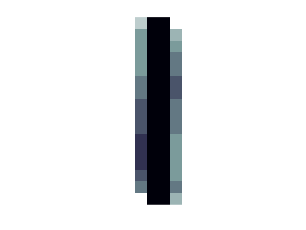

ima(testDigits(:,:,randImgIndex))
ima(sumDigit(:,:,minDigit + 1))

% ladda centroider i centroidDigit
disp('new part')

new part


centroidDigit = zeros(16,16,10);
for digit = 0:9
    indexDigit = find(trainAns == digit);
    for c = 1:length(indexDigit)
        indexValue = indexDigit(c);
        centroidDigit(:,:,digit + 1) = centroidDigit(:,:,digit + 1) + trainDigits(:,:,indexValue);
    end
    centroidDigit(:,:,digit + 1) = centroidDigit(:,:,digit + 1)./length(indexDigit);
end

% gå genom test bilderna mot att centroider
centroidResults = zeros(length(testAns), 3);
centroidResults(:, 1) = testAns;

for currentIndex = 1:length(testAns)

    currentResult = zeros(10,1);

    for digit = 0:9
        currentResult(digit + 1) = abs(norm(centroidDigit(:,:,digit + 1) - testDigits(:,:,currentIndex)));
    end
    currentResult;
    [MinValue1,I] = min(currentResult);
    centroidResults(currentIndex,2) = I-1;
    % this part adds the values in the third col, 
    % which shows "how sure the algorithm is about the prediction"
    resultsWithoutMinValue = currentResult(currentResult~=currentResult(I));
    [MinValue2,~] = min(resultsWithoutMinValue);
    centroidResults(currentIndex, 3) = MinValue2 - MinValue1;
end
centroidResults

centroidResults =     9.0000    9.0000    0.0582
    6.0000    2.0000    0.1884
    3.0000    3.0000    1.1830
    6.0000    2.0000    0.1792
    6.0000         0    0.0353
         0         0    1.9684
         0         0    1.0394
         0         0    1.3278
    6.0000    6.0000    0.9637
    9.0000    9.0000    0.1961


amountWrong = zeros(10,1);
procentAndel = zeros(10,1);
totWrong = 0

totWrong = 0

for digit = 0:9
    allOfDigit = find(centroidResults(:,1) == digit);
    for index = 1:length(allOfDigit)
        indexOfCurrent = allOfDigit(index);
        if centroidResults(indexOfCurrent,1) ~= centroidResults(indexOfCurrent,2)
            amountWrong(digit + 1) = amountWrong(digit + 1) + 1;
        end
    end
    totWrong = totWrong + amountWrong(digit + 1);
    procentAndel(digit +1) = amountWrong(digit+1)/(length(find(testAns == digit)));
end
disp('THis is the total amount wrong')

THis is the total amount wrong


totWrong/length(testAns)

ans = 0.2232

procentAndel.*100

ans =    17.5487
    4.5455
   31.8182
   30.1205
   29.0000
   33.1250
   19.4118
   19.7279
   31.3253
   19.7740


amountWrong

amountWrong =     63
    12
    63
    50
    58
    53
    33
    29
    52
    35


% calc 3 most false with max margin

tempVector = centroidResults(:,3)

tempVector =     0.0582
    0.1884
    1.1830
    0.1792
    0.0353
    1.9684
    1.0394
    1.3278
    0.9637
    0.1961



[sortedVals,indexes] = sort(tempVector)

sortedVals =     0.0000
    0.0001
    0.0004
    0.0018
    0.0019
    0.0022
    0.0022
    0.0024
    0.0032
    0.0034


indexes =          807
        1427
         529
        1532
         808
        1961
        1309
         861
         336
        1601



centroidResults(indexes(1), :)

ans =     3.0000    3.0000    0.0000


wrongIndexValues = zeros(3,1);
n = 1;
ind = length(sortedVals)

ind = 2007

while n ~= 4

    if centroidResults(indexes(ind), 1) == 4 && centroidResults(indexes(ind), 2) ~= 4
        wrongIndexValues(n) = indexes(ind)
        n = n + 1;
    end
    
    ind = ind -1;
end

wrongIndexValues =    971
     0
     0


wrongIndexValues =          971
        1805
           0


wrongIndexValues =          971
        1805
         772


% calc 3 correct with max margin
tempVector = centroidResults(:,3)

tempVector =     0.0582
    0.1884
    1.1830
    0.1792
    0.0353
    1.9684
    1.0394
    1.3278
    0.9637
    0.1961



[sortedVals,indexes] = sort(tempVector)

sortedVals =     0.0000
    0.0001
    0.0004
    0.0018
    0.0019
    0.0022
    0.0022
    0.0024
    0.0032
    0.0034


indexes =          807
        1427
         529
        1532
         808
        1961
        1309
         861
         336
        1601



n = 1;
ind = 1

ind = 1

correctIndexValues = zeros(3,1)

correctIndexValues =      0
     0
     0


while n ~= 4
    if (centroidResults(indexes(ind),1) == 4) && (centroidResults(indexes(ind),2) == 4)
        correctIndexValues(n) = indexes(ind)
        n = n + 1;
    end

    ind = ind + 1;
    n;
end

correctIndexValues =         1386
           0
           0


correctIndexValues =         1386
        1281
           0


correctIndexValues =         1386
        1281
         913


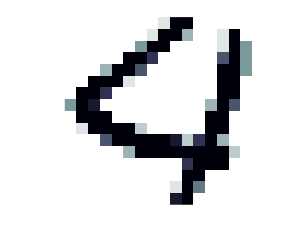


ima(testDigits(:,:,correctIndexValues(1)))
ima(testDigits(:,:,correctIndexValues(2)))

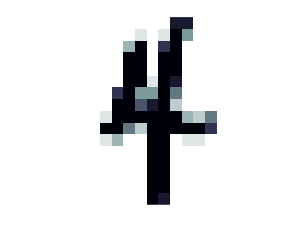

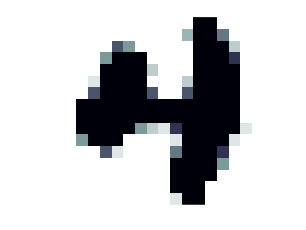

ima(testDigits(:,:,correctIndexValues(3)))

% first closest neighbooors 
disp('new part')

new part



%kolTrainDigits = reshape(trainDigits, [256, 1, 7291]);
neighboorResults = zeros(length(testAns), 2);
neighboorResults(:, 1) = testAns;


for testIndex = 1:length(testAns)
    savedIndex = 0;
    savedDiff = 1e3;
    for trainIndex = 1:length(trainAns)
        tempDiff = abs(norm(testDigits(:,:,testIndex) - trainDigits(:,:,trainIndex)));
        if tempDiff < savedDiff
            savedDiff = tempDiff;
            neighboorResults(testIndex, 2) = trainAns(trainIndex);
        end
    end
end 
neighboorResults

neighboorResults =      9     9
     6     6
     3     3
     6     6
     6     6
     0     0
     0     0
     0     0
     6     6
     9     9


amountWrong = zeros(10,1);
procentAndel = zeros(10,1);
totWrong = 0;
for digit = 0:9
    allOfDigit = find(neighboorResults(:,1) == digit);
    for index = 1:length(allOfDigit)
        indexOfCurrent = allOfDigit(index);
        if neighboorResults(indexOfCurrent,1) ~= neighboorResults(indexOfCurrent,2)
            amountWrong(digit + 1) = amountWrong(digit + 1) + 1;
        end
    end
    totWrong = totWrong + amountWrong(digit + 1);
    procentAndel(digit +1) = amountWrong(digit+1)/(length(find(testAns == digit)));
end
disp('This is the tot wrong with nearest')
totWrong/length(testAns)
procentAndel.*100

ans =     1.6713
    3.7879
   10.1010
   10.8434
    9.5000
    8.7500
    5.2941
    7.4830
    9.0361
    2.2599


amountWrong

amountWrong =      6
    10
    20
    18
    19
    14
     9
    11
    15
     4
